esercizio 1

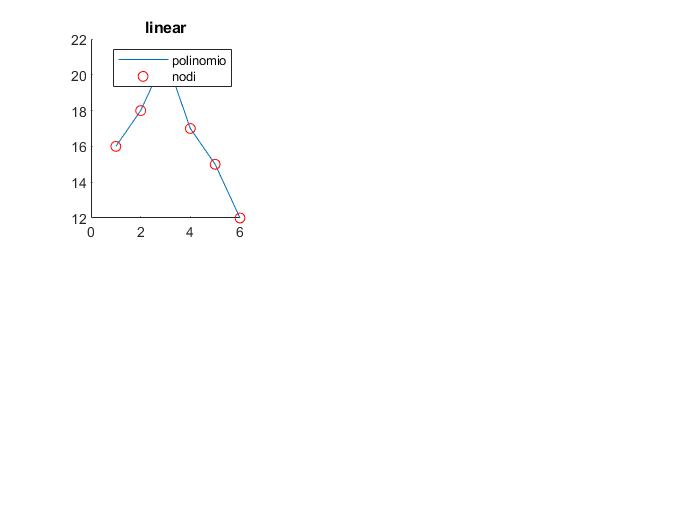

clear all
x=1:6;
y=[16 18 21 17 15 12];
z=1:0.2:6;
p=interp1(x,y,z);
pl=interp1(x,y,z,"linear");
pSp=interp1(x,y,z,"spline");
pN=interp1(x,y,z,"nearest");
pP=interp1(x,y,z,"pchip");
pC=interp1(x,y,z,"cubic");
subplot(2,3,1)
hold on
plot(z,p)
plot(x,y,"or")
legend("polinomio","nodi")
title("linear")

Esercizio 9

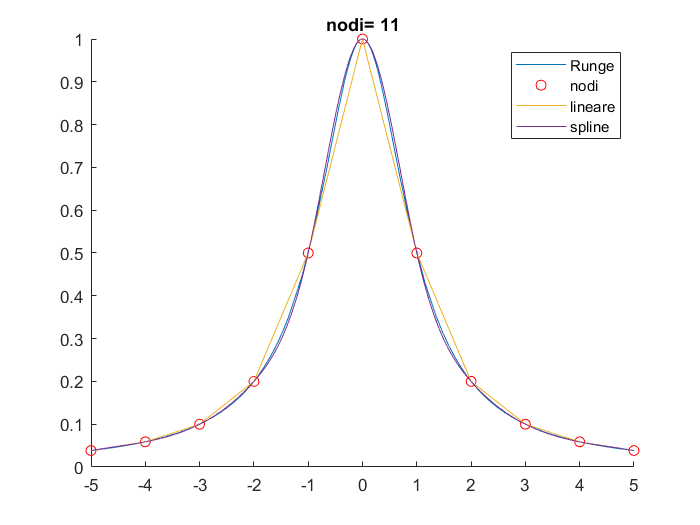

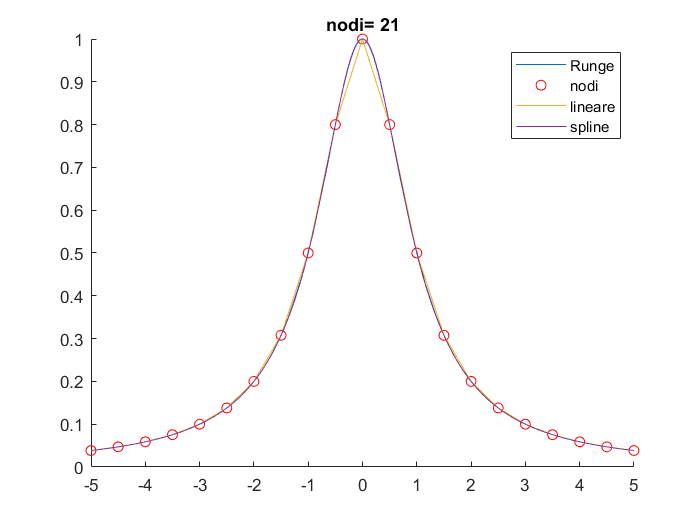

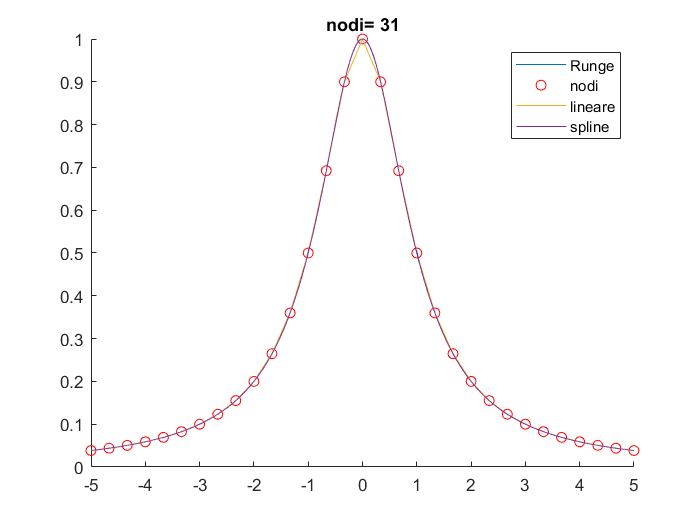

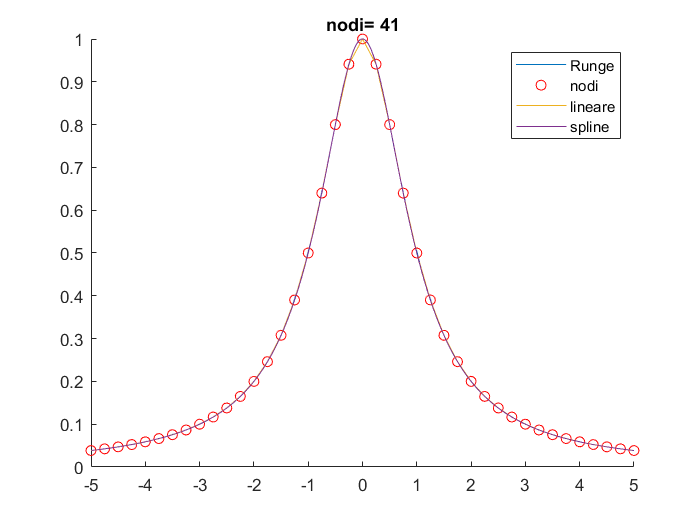

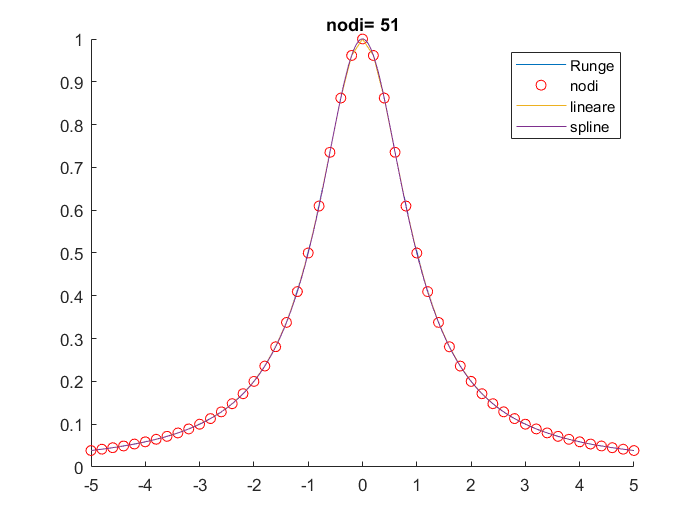

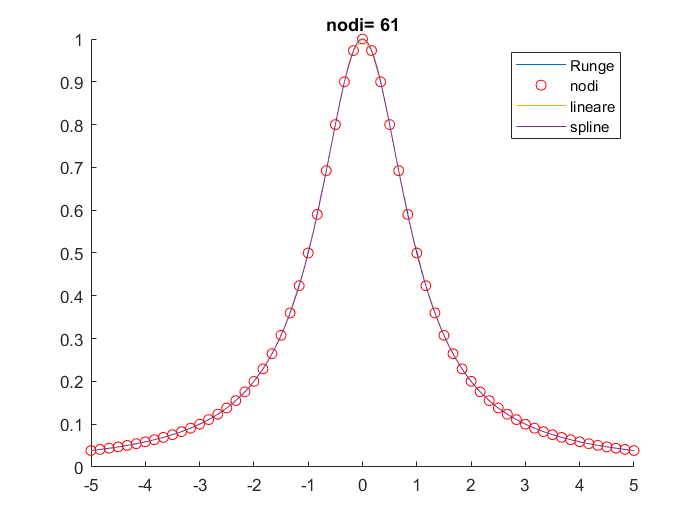

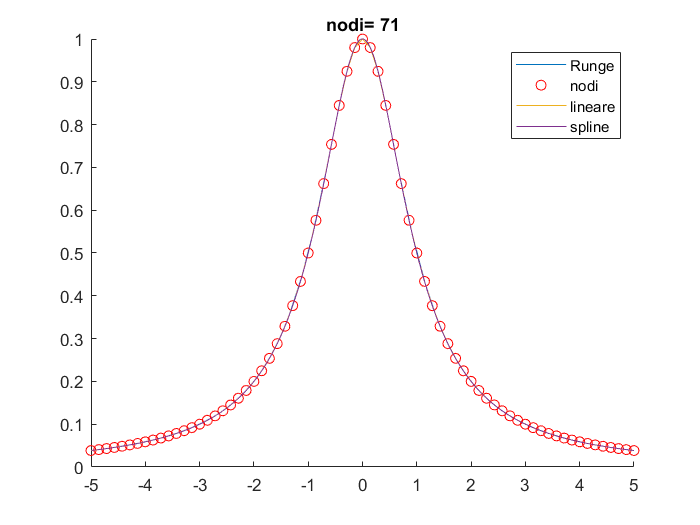

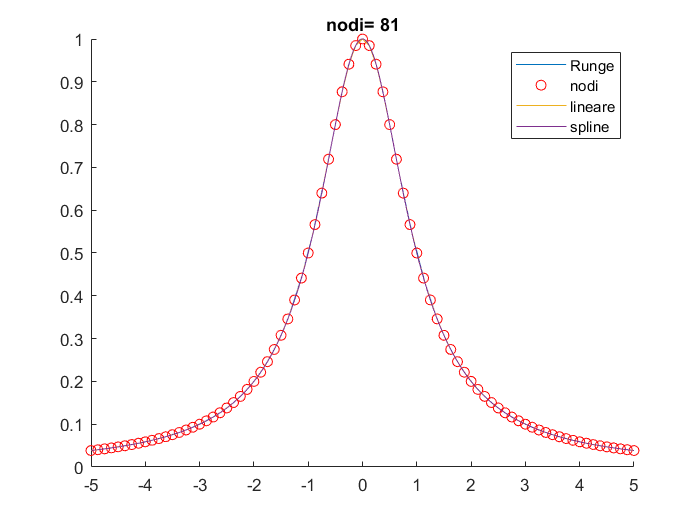

clear all
f=@(x) 1./(1+x.^2);
N=10000;
a=-5;b=5;
X=linspace(-5,5,N);
fn=f(X);
err=[];
err1=[];
for V=10:10:100
    figure()
    hold on
    title(['nodi= ',num2str(V+1)])
    fplot(f,[-5 5])
    x=linspace(-5,5,V+1);
    y=f(x);
    plot(x,y,"or")
    t1=interp1(x,y,X);
    t2=interp1(x,y,X,"spline");
    
    plot(X,t1,X,t2)
    
    e=norm(fn-t1,"inf");
    err=[err e];
    e1=norm(fn-t2,"inf");
    err1=[err1 e1];
    legend("Runge","nodi","lineare","spline")
end

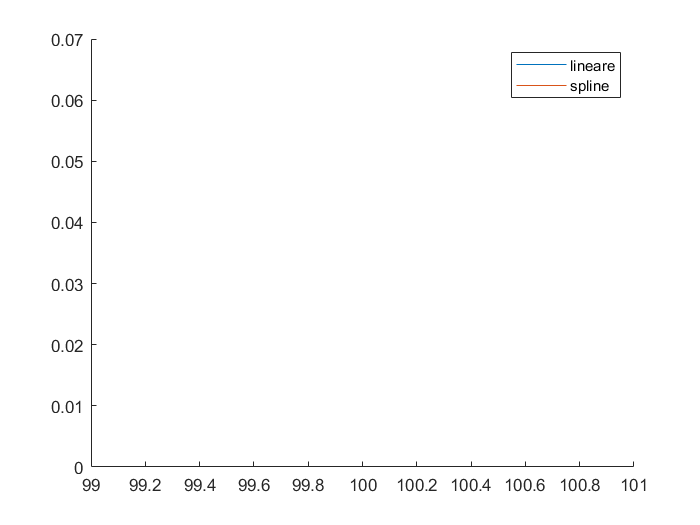

figure()
hold on
loglog(V,err)
loglog(V,err1)
h=(b-a)./V;
%loglog(V,h,V,h.^2,V,h^4)
legend("lineare","spline")

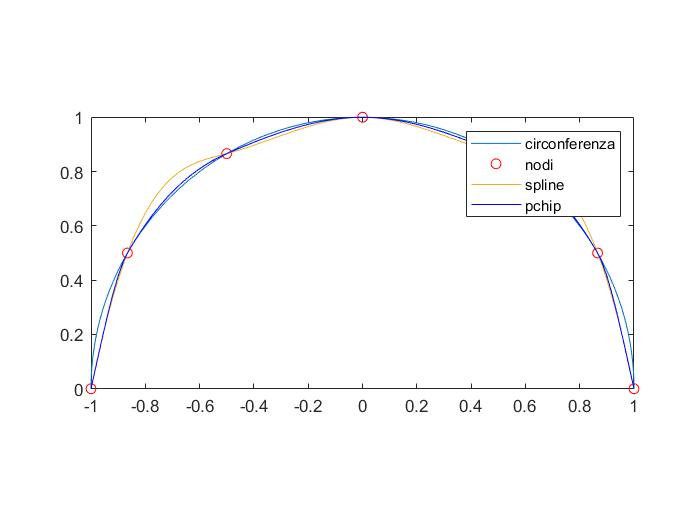

clear all
close all
f=@(x) sqrt(1-x.^2);
k=0:6;
xk=-cos(k.*pi/6);
yk=sin(k.*pi/6);
N=100;
a=-1;b=1;
z=linspace(a,b,N);
t1=interp1(xk,yk,z,"spline");
t2=interp1(xk,yk,z,"pchip");
fplot(f,[a b])
hold on
plot(xk,yk,"or",z,t1,z,t2,"b")
legend("circonferenza","nodi","spline","pchip")
axis equal

Approssimazione dati

clear all
close all
load datiOhm.mat
a=-1;b=46;N=100;
p=polyfit(I,V,12);

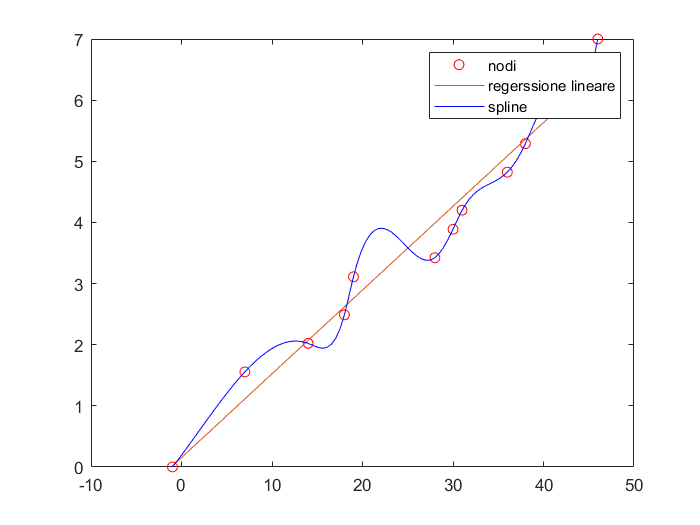

pr=polyfit(I,V,1);
z=linspace(a,b,N);
y=polyval(p,z);
yr=polyval(pr,z);
t=interp1(I,V,z,"spline");
plot(I,V,"or",z,yr,z,t,"b")
legend("nodi","regerssione lineare","spline")

retta=polyval(pr,I);
scarto_quadratico=norm(V-retta)^2

scarto_quadratico = 1.2955

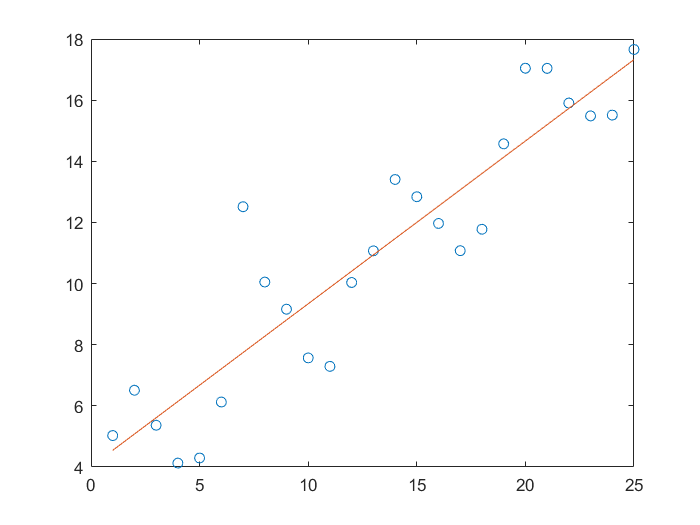

clear all
close all
dati
plot(t,y,"o")
hold on
p=polyfit(t,y,1);
retta=polyval(p,t);
plot(t,retta)

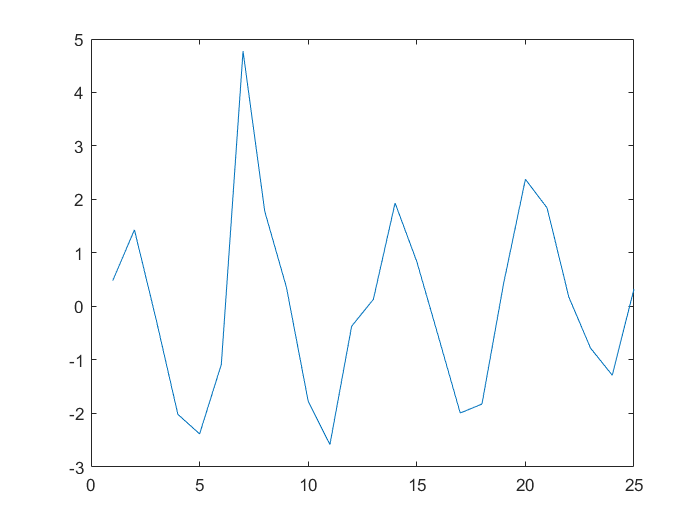

figure
residui=y-retta;
plot(residui)

scarto_quadratico=norm(residui)^2

scarto_quadratico = 72.9517

[anomalo,indice]=max(abs(residui))

anomalo = 4.7728

indice = 7

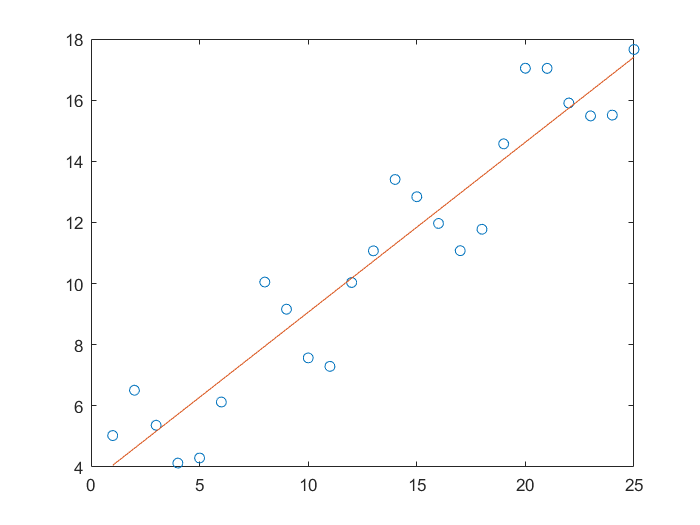

i=find(abs(residui)==anomalo);
t(indice)=[];
y(indice)=[];
figure
plot(t,y,"o")
hold on
p=polyfit(t,y,1);
retta=polyval(p,t);
plot(t,retta)

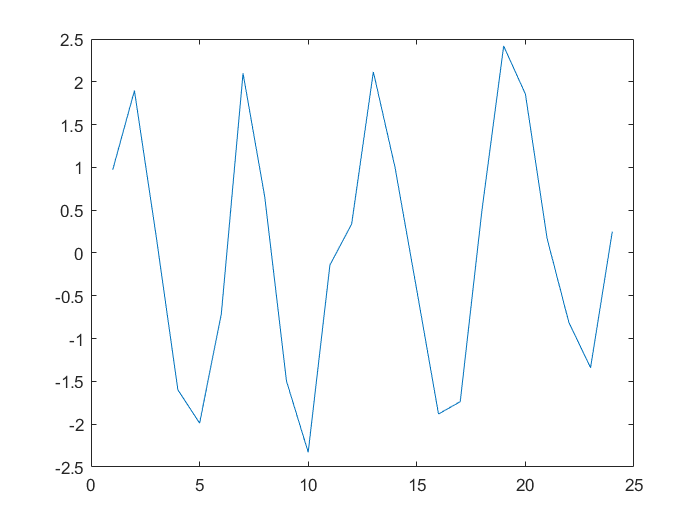

figure
residui=y-retta;
plot(residui)

scarto_quadratico=norm(residui)^2

scarto_quadratico = 48.5180

[anomalo,indice]=max(abs(residui))

anomalo = 2.4178

indice = 19

B=[ones(size(t)) t sin(t)]

B =     1.0000    1.0000    0.8415
    1.0000    2.0000    0.9093
    1.0000    3.0000    0.1411
    1.0000    4.0000   -0.7568
    1.0000    5.0000   -0.9589
    1.0000    6.0000   -0.2794
    1.0000    8.0000    0.9894
    1.0000    9.0000    0.4121
    1.0000   10.0000   -0.5440
    1.0000   11.0000   -1.0000


beta=B\y

beta =     3.1536
    0.5869
    1.9733


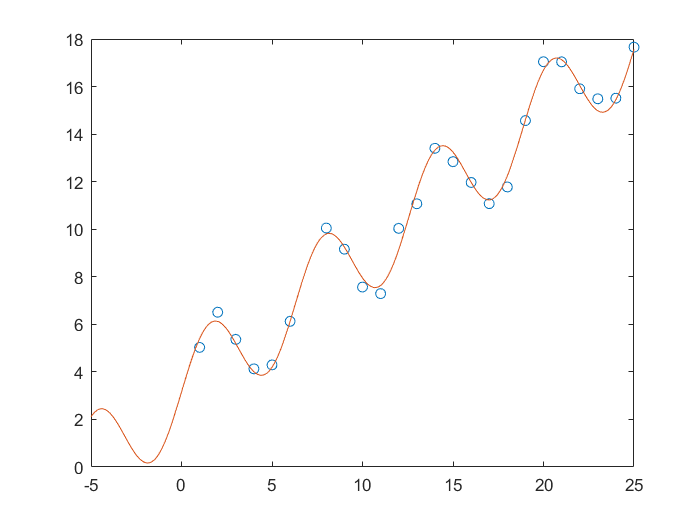

g=@(x) beta(1)+beta(2)*x+beta(3)*sin(x);
figure
plot(t,y,"o")
hold on
fplot(g)